# Risolve Testing

## **Testing di robustezza**

### **Testing sul numero di input**

A=rand(100,100);
x=ones(100,1);
b=A*x;
y=risolve(A,b)

Error using risolve (line 6)
Inserire i 3 parametri di input: Matrice, vettore e struttura.

### **Testing sulla matrice**

Testo se non è una matrice

A=rand(100,100,100);
x=ones(100,1);
b=[1:100]';
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 10)
Il primo input deve essere una matrice.

Testo se non è quadrata

A=rand(50,100);
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 14)
La matrice deve essere quadrata.

Testo se è sparsa o vuota

A=sparse(rand(100,100));
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 12)
La matrice non deve essere sparsa o vuota.

A=[];
x=ones(100,1);
b=x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 12)
La matrice non deve essere sparsa o vuota.

Testo se non contiene numeri reali

A=rand(100,100);
A(50,92)=Inf;
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 16)
Gli elementi della matrice devono essere numeri reali double finiti.

A=rand(100,100);
A(14,10)=NaN;
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 16)
Gli elementi della matrice devono essere numeri reali double finiti.

**Testing sul vettore**

Testo se non è un vettore

A=rand(100,100);
x=ones(100,1);
b=4;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 21)
Errore, b deve essere un vettore colonna.

Testo se non è un vettore colonna

A=rand(100,100);
x=ones(100,1);
b=[2 3];
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 21)
Errore, b deve essere un vettore colonna.

Testo se il vettore e la matrice hanno dimensioni diverse

A=rand(100,100);
x=ones(100,1);
b=[A*x; 10];
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 23)
Il vettore b e la matrice A hanno dimensioni diverse.

Testo se non contiene reali finiti double

A=rand(100,100);
x=ones(100,1);
b=A*x;
b(30)=Inf;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 25)
Errore, b deve contenere reali finiti double.

**Testing sulla struttura**

Testo se non è una struttura

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt=29;
y=risolve(A,b,opt)

Error using risolve (line 30)
Il terzo parametro deve essere una struttura

Testo se non ha tre campi

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
opt.quarto=true;
y=risolve(A,b,opt)

Error using risolve (line 32)
La struttura deve avere tre campi.

Testo se i campi non hanno i nomi specificati

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.campo=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve (line 34)
I tre campi della struttura opt devono chiamarsi full, sup e inf.

Testo se i campi della struttura non sono logici

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=5;
y=risolve(A,b,opt)

Error using risolve (line 36)
I tre campi della struttura devono essere logici (true/false).

Testo se il numero di campi true è diverso da uno

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=true;
opt.full=false;
y=risolve(A,b,opt)

Error using risolve (line 38)
Uno e un solo campo della struttura deve essere true.

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

Error using risolve (line 38)
Uno e un solo campo della struttura deve essere true.

**Testing sugli algoritmi**

Testo se alla back substitution è messa in ingresso una matrice singolare

A=rand(100,100);
A=triu(A)+diag(ones(100,1));
A(25,25)=0;
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=true;
opt.full=false;
y=risolve(A,b,opt)

Error using risolve>back_sub (line 55)
Back Substitution: La matrice è singolare.

Error in risolve (line 44)
        x=back_sub(A,b);

Testo se alla forward substitution è messa in ingresso una matrice singolare

A=rand(100,100);
A=tril(A)+diag(ones(100,1));
A(50,50)=0;
x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

Error using risolve>forward_sub (line 67)
Forward Substitution: La matrice è singolare.

Error in risolve (line 46)
        x=forward_sub(A,b);

Testo se nella funzione Gauss il sistema è singolare.

A=rand(100,100);
A(50,:)=0;
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

Error using risolve>gauss (line 98)
Gauss:Il sistema è singolare.

Error in risolve (line 48)
        x=gauss(A,b);

## **Testing di Funzionamento**

Testing funzionamento back substitution

A=rand(100,100);
A=triu(A)+diag(ones(100,1));
cond=cond(A)

cond =      8.312082505603721e+02


x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=true;
opt.full=false;
y=risolve(A,b,opt)

y =    0.999999999999963   1.000000000000004   0.999999999999984   1.000000000000000   1.000000000000012   0.999999999999977   1.000000000000014   1.000000000000024   1.000000000000017   0.999999999999988   1.000000000000011   0.999999999999977   0.999999999999981   1.000000000000000   1.000000000000004   1.000000000000004   1.000000000000013   0.999999999999991   0.999999999999990   1.000000000000004   1.000000000000004   0.999999999999998   0.999999999999981   1.000000000000029   1.000000000000028   1.000000000000011   1.000000000000004   0.999999999999967   0.999999999999983   1.000000000000010   0.999999999999994   1.000000000000007   1.000000000000013   0.999999999999987   1.000000000000002   1.000000000000007   1.000000000000012   0.999999999999986   1.000000000000000   1.000000000000000   0.999999999999997   0.999999999999996   0.999999999999991   0.999999999999997   1.000000000000007   1.000000000000003   1.000000000000006   1.000000000000006   1.000000000000001   0.99999999999

Testing funzionamento forward substitution

A=rand(100,100);
A=tril(A)+diag(ones(100,1));
cond=cond(A)

cond =      6.726834166225296e+02


x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

y =    1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000001   0.999999999999999   1.000000000000001   1.000000000000001   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000001   0.999999999999999   1.000000000000000   1.000000000000000   1.000000000000002   0.999999999999997   1.000000000000001   1.000000000000000   1.000000000000002   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000002   0.999999999999998   1.000000000000001   1.000000000000002   1.000000000000001   0.999999999999998   1.000000000000004   1.000000000000002   0.999999999999994   0.999999999999994   0.999999999999997   1.000000000000008   1.000000000000000   0.999999999999999   0.999999999999994   1.000000000000004   1.000000000000001   1.000000000000001   1.000000000000005   0.999999999999988   0.99999999999

Testing funzionamento gauss pivoting parziale virtuale

A=rand(100,100);
x=ones(100,1);
cond=cond(A)

cond =      1.428581994186444e+03


b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

y =    1.000000000000099   1.000000000000009   1.000000000000001   1.000000000000056   0.999999999999988   1.000000000000008   0.999999999999931   0.999999999999895   0.999999999999975   1.000000000000041   0.999999999999949   0.999999999999966   1.000000000000014   1.000000000000010   1.000000000000018   0.999999999999881   1.000000000000018   1.000000000000047   1.000000000000066   0.999999999999891   1.000000000000080   1.000000000000079   1.000000000000106   0.999999999999949   1.000000000000084   0.999999999999964   1.000000000000097   0.999999999999987   0.999999999999947   1.000000000000038   0.999999999999987   0.999999999999973   0.999999999999987   1.000000000000000   1.000000000000033   0.999999999999974   1.000000000000068   1.000000000000062   1.000000000000085   0.999999999999980   1.000000000000060   0.999999999999932   0.999999999999938   0.999999999999924   0.999999999999884   0.999999999999949   1.000000000000021   0.999999999999979   1.000000000000035   0.99999999999

## Verifica teorema di Wilkinson

Verifica per gauss pivoting parziale virtuale

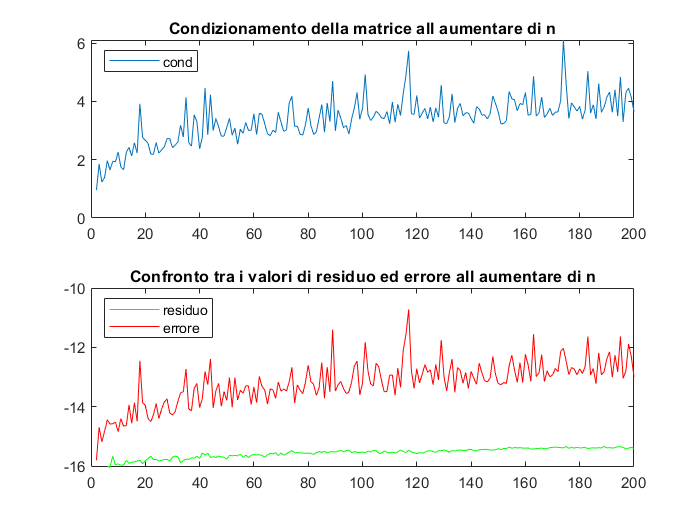

opt.inf=false;
opt.sup=false;
opt.full=true;
for n=2:200
    A=rand(n,n);
    x=2*ones(n,1);
    b=A*x;
    c(n)=cond(A);
    y=risolve(A,b,opt);
    re(n)=norm(A*y'-b)/(norm(A)*norm(y));
    er(n)=norm(x-y')/norm(x);
end
close all;
x=1:200;
subplot(2,1,1)
plot(x,log10(c))
title('Condizionamento della matrice all aumentare di n');
legend('cond','Location','northwest');
subplot(2,1,2)
plot(x,log10(re),'g')
hold on;
plot(x,log10(er),'r')
title('Confronto tra i valori di residuo ed errore all aumentare di n');
legend('residuo','errore','Location','northwest');

Verifica per una matrice malcondizionata

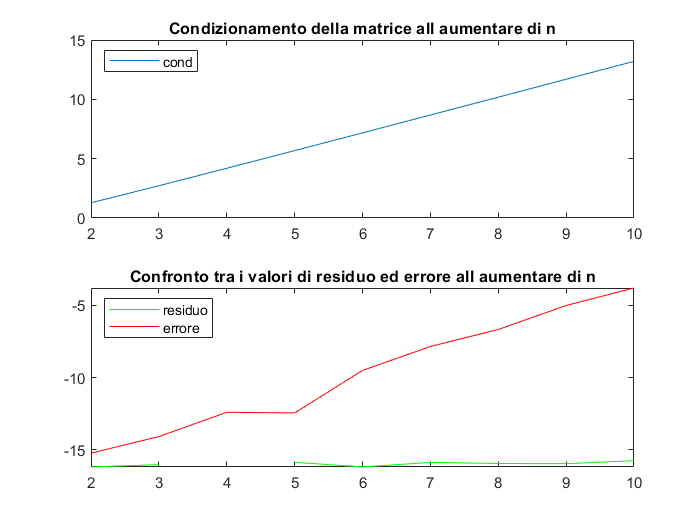

opt.inf=false;
opt.sup=false;
opt.full=true;
for n=2:10
    H=hilb(n);
    x=2*ones(n,1);
    b=H*x;
    c(n)=cond(H);
    y=risolve(H,b,opt);
    re(n)=norm(H*y'-b)/(norm(H)*norm(y));
    er(n)=norm(x-y')/norm(x);
end
close all;
x=1:10;
subplot(2,1,1)
plot(x,log10(c))
title('Condizionamento della matrice all aumentare di n');
legend('cond','Location','northwest');
subplot(2,1,2)
plot(x,log10(re),'g')
hold on;
plot(x,log10(er),'r')
title('Confronto tra i valori di residuo ed errore all aumentare di n');
legend('residuo','errore','Location','northwest');

Si nota che l'indice di condizionamento della matrice di hilbert è molto più grande rispetto agli altri casi anche se la dimensione della metrice è inferiore, quindi l'errore è da subito molto elevato.

## **Testing di Accuratezza**

Calcolo l'errore della back substitution

A=rand(100,100);
A=triu(A)+diag(ones(100,1));
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=true;
opt.full=false;
y=risolve(A,b,opt)

y =    0.999999999999978   0.999999999999994   1.000000000000024   1.000000000000027   1.000000000000022   0.999999999999973   0.999999999999985   1.000000000000041   1.000000000000000   1.000000000000007   0.999999999999991   0.999999999999996   1.000000000000010   0.999999999999995   0.999999999999987   1.000000000000002   1.000000000000010   0.999999999999987   0.999999999999989   1.000000000000017   1.000000000000000   1.000000000000003   1.000000000000002   1.000000000000006   1.000000000000008   0.999999999999997   0.999999999999995   0.999999999999975   1.000000000000007   1.000000000000009   0.999999999999996   1.000000000000011   0.999999999999997   1.000000000000009   0.999999999999990   0.999999999999989   1.000000000000011   1.000000000000001   0.999999999999995   0.999999999999996   0.999999999999999   1.000000000000003   0.999999999999997   1.000000000000002   0.999999999999990   1.000000000000006   0.999999999999998   1.000000000000006   1.000000000000002   1.00000000000

cond=cond(A)

cond =      6.147176731527594e+02


err=norm(x-y')/norm(x)

err =      8.963894223692580e-15


Calcolo l'errore della forward substitution

A=rand(100,100);
A=tril(A)+diag(ones(100,1));
x=ones(100,1);
b=A*x;
opt.inf=true;
opt.sup=false;
opt.full=false;
y=risolve(A,b,opt)

y =    1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000001   1.000000000000001   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000000   1.000000000000000   0.999999999999999   1.000000000000001   1.000000000000000   0.999999999999999   0.999999999999998   1.000000000000002   1.000000000000000   0.999999999999998   0.999999999999999   1.000000000000006   1.000000000000004   0.999999999999997   1.000000000000002   1.000000000000002   0.999999999999996   0.999999999999995   1.000000000000001   1.000000000000000   1.000000000000000   1.000000000000009   0.999999999999994   0.999999999999998   1.000000000000002   0.999999999999997   0.999999999999999   1.000000000000001   0.999999999999994   1.00000000000

cond=cond(A)

cond =      6.468495855578952e+02


err=norm(x-y')/norm(x)

err =      1.194100992187620e-14


Calcolo l'errore della funzione di gauss

A=rand(100,100);
x=ones(100,1);
b=A*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(A,b,opt)

y =    1.000000000000069   1.000000000000059   0.999999999999969   0.999999999999978   0.999999999999992   0.999999999999957   1.000000000000038   1.000000000000069   0.999999999999989   1.000000000000049   1.000000000000078   1.000000000000000   1.000000000000038   1.000000000000011   1.000000000000026   1.000000000000037   0.999999999999972   0.999999999999984   1.000000000000053   0.999999999999978   0.999999999999943   1.000000000000003   1.000000000000044   0.999999999999939   1.000000000000014   1.000000000000010   0.999999999999914   0.999999999999913   1.000000000000012   0.999999999999973   0.999999999999966   1.000000000000001   0.999999999999960   1.000000000000062   1.000000000000032   1.000000000000006   0.999999999999971   1.000000000000085   1.000000000000033   0.999999999999997   1.000000000000006   1.000000000000033   1.000000000000061   0.999999999999926   0.999999999999980   0.999999999999876   0.999999999999865   1.000000000000035   1.000000000000050   0.99999999999

cond=cond(A)

cond =      1.488908940672050e+03


err=norm(x-y')/norm(x)

err =      5.692492820360561e-14


Calcolo l'errore con una matrice malcondizionata

H=hilb(10);
x=ones(10,1);
b=H*x;
opt.inf=false;
opt.sup=false;
opt.full=true;
y=risolve(H,b,opt)

y =    0.999999999095414   1.000000077638003   0.999998354294756   1.000014906295678   0.999929106136443   1.000194425970866   0.999681635015208   1.000307148615795   0.999838981464458   1.000035366078449


cond=cond(H)

cond =      1.602502816811318e+13


err=norm(x-y')/norm(x)

err =      1.630725525898540e-04
